# MAE 6760 Model Based Estimation - Final Project

### Saksham Kaushik (sk2482)

## Dynamics Model

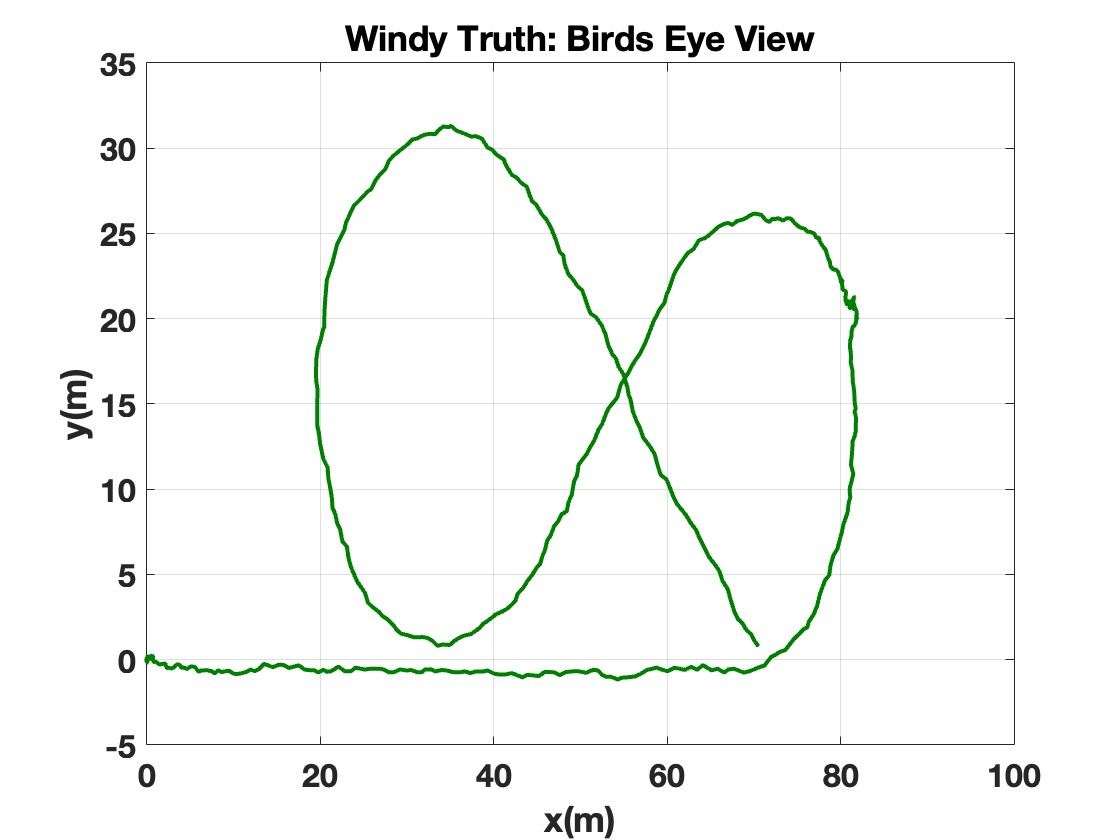

rng(100);
clear;
scenario_type = 'two';
[Uacc,Uomega]=get_controlinputs(scenario_type);

dt=0.1;
nt=length(Uacc);
t=[0:dt:dt*(nt-1)];
n=4;

Qc = diag([1.5 1.5]);
w = sqrtm(Qc)*randn(2,nt);
[Xtrue]=simulate_2Dbike(Uacc,Uomega,w);

figure(1);
plot_birdseyeview(Xtrue,[],[],'Windy Truth: Birds Eye View');

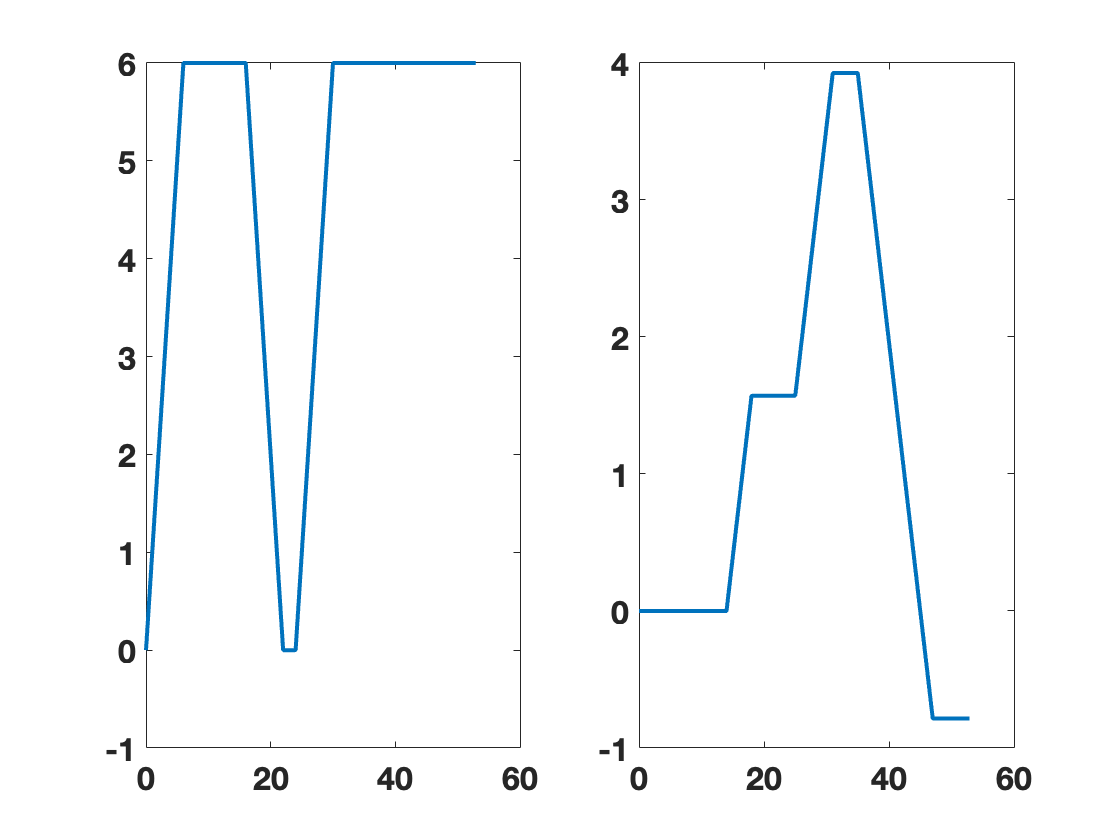

figure(20)
subplot(1,2,1);
plot(t,Xtrue(3,:))
subplot(1,2,2);
plot(t,Xtrue(4,:))
PrepFigPresentation(20);

## Create Measurements (x,y,V):

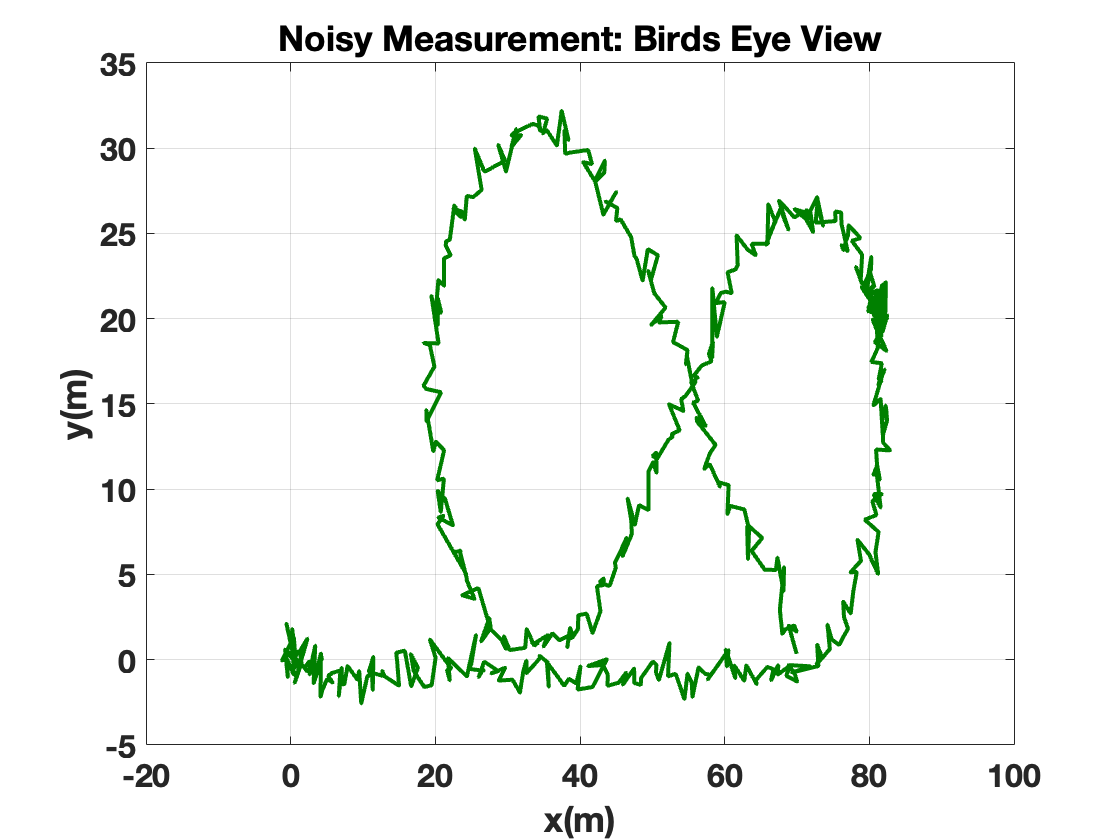

nz=3;
R=diag([0.5 0.5 0.5]);
v=sqrtm(R)*randn(nz,nt);
Z=[Xtrue(1:3,:)] + v;

plot_birdseyeview(Z,[],[],'Noisy Measurement: Birds Eye View');

## Sigma Points Filter:

%SIGMA POINTS FILTER
ffun = 'predict_state_bike_euler';
hfun = 'predict_msmt_bike';
nsig = 3;
P0= diag([1^2, 1^2 1^2 1^2]);
xhatu=[0;0;0;0];Pu(1:n,1:n,1)=P0;
Qd = Qc/dt;
G = [dt,0;0,dt;0,0;0,0];
Qx = G*Qd*G';
% 
for k = 1:(nt-1)
    Uk = [Uacc(k);Uomega(k)];
    zkp1 = Z(:,k+1);
    [xhatu(:,k+1),Pu(1:n,1:n,k+1),xPred,zPred,innovation] = ...
        spf_bike(xhatu(:,k),Pu(1:n,1:n,k),Uk,Qx,ffun,zkp1,R,hfun,t(k),t(k+1),nsig);
end

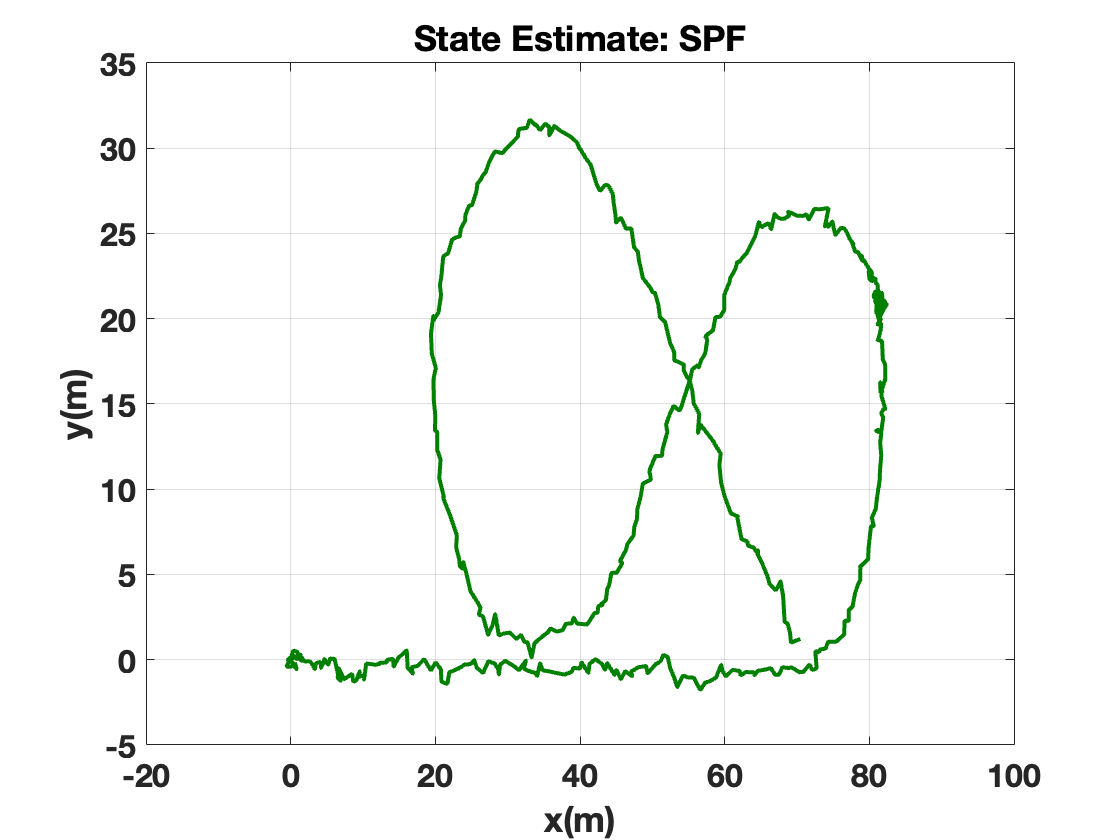

plot_birdseyeview(xhatu(1:2,:),[],[],'State Estimate: SPF');

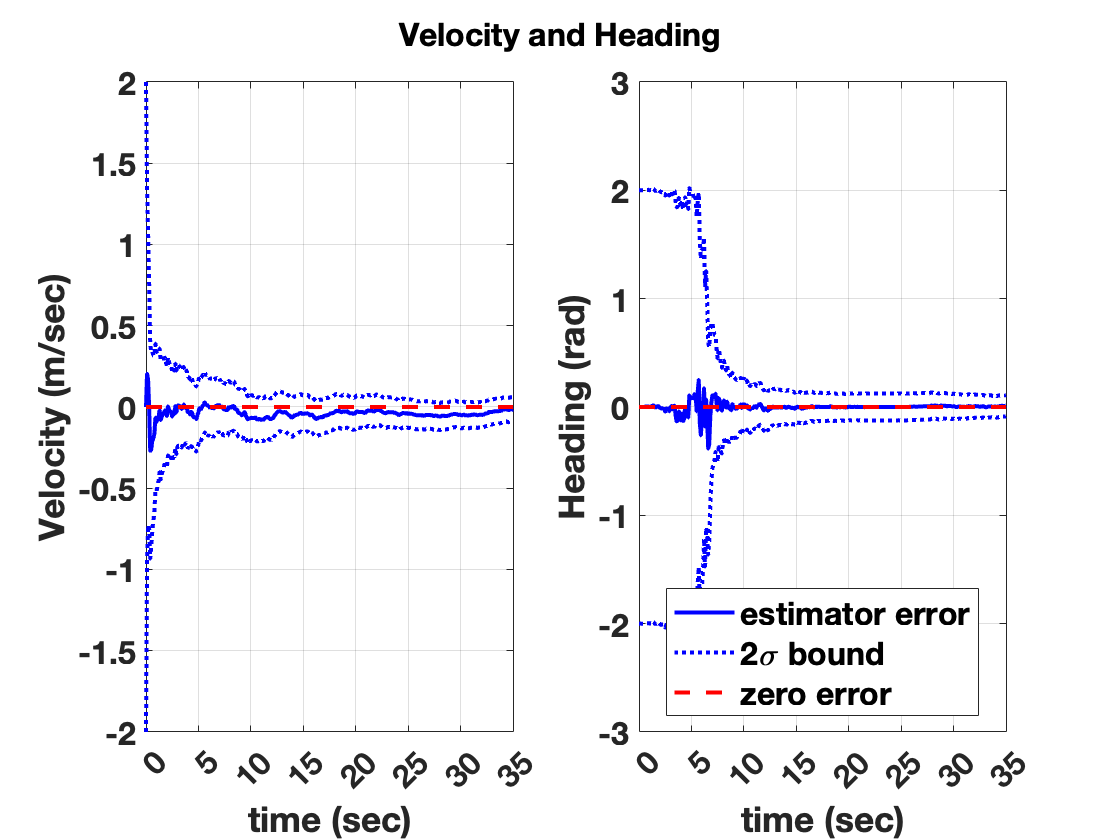

plot_estimator_error(t,Xtrue,xhatu,Pu,[3 4],'Velocity and Heading')

## Particle Filter

ns = 1000; %number of particles
pd_0 = makedist('Normal',0,0.5);
nx = 4;

%Measurement Likelihood model - multivar
Lx = makedist('Normal',0,0.5);
x_0 = random(pd_0,ns,1);
y_0 = random(pd_0,ns,1);
V_0 = random(pd_0,ns,1);
theta_0 = random(pd_0,ns,1);

X = zeros(ns,nx,nt);
X(:,:,1) = [x_0,y_0,V_0,theta_0];

W=zeros(ns,nt);
W(:,1) = ones(ns,1)/ns;

xEst=zeros(nt,nx);xEst(1,:)=mean(X(:,:,1),1);
xSig=zeros(nt,nx);xSig(1,:)=std(X(:,:,1),1).^2;

Neff_thresh=ns;

Particle filter loop:

for k = 2:nt
    Xprior = X(:,:,k-1);
    Uprior = [Uacc(k-1),Uomega(k-1)];
    w = randn(ns,2)*sqrt(2*Qc);
    
    %PREDICTION STEP
    Xpred = predict_state_bike_euler(Xprior',Uprior,w',t(k-1),t(k))';
   
    %UPDATE STEP
    Zcurr = Z(:,k)';
    Zhat = Xpred(:,1:3);
    Inn = ones(ns,1)*Zcurr - Zhat;
    
    %calculate likelihood weighting for each particle
    L = mvnpdf(Inn,zeros(1,3),R);
    %UPDATE WEIGHTS
    Wk_unnorm=W(:,k-1).*L;%update weight with unnormalized likelihood
    Wk=Wk_unnorm/sum(Wk_unnorm); %normalize all weights to sum to 1
    
    %Resampling
    Neff = 1/[Wk'*Wk];
    
    if Neff < Neff_thresh
        
        CDF = cumsum(Wk)/sum(Wk);
        CDF_plus=CDF+rand(ns,1)*1E-6;
        
        iSelect  = rand(ns,1);
        iNextGeneration = interp1(CDF_plus,1:ns,iSelect,'nearest','extrap');
        
        X(:,:,k) = Xpred(iNextGeneration,:);
        W(:,k) = ones(ns,1)/ns;
    else
        X(:,:,k) = Xpred;
        W(:,k)=Wk;
    end
    
    xEst(k,:) = sum(Wk.*X(:,:,k),1);
    xSig(k,:) = sqrt([sum(Wk.*(X(:,1,k)-xEst(k,1)).^2,1) sum(Wk.*(X(:,2,k)-xEst(k,2)).^2,1) ...
        sum(Wk.*(X(:,3,k)-xEst(k,3)).^2,1) sum(Wk.*(X(:,4,k)-xEst(k,4)).^2,1)]);
end

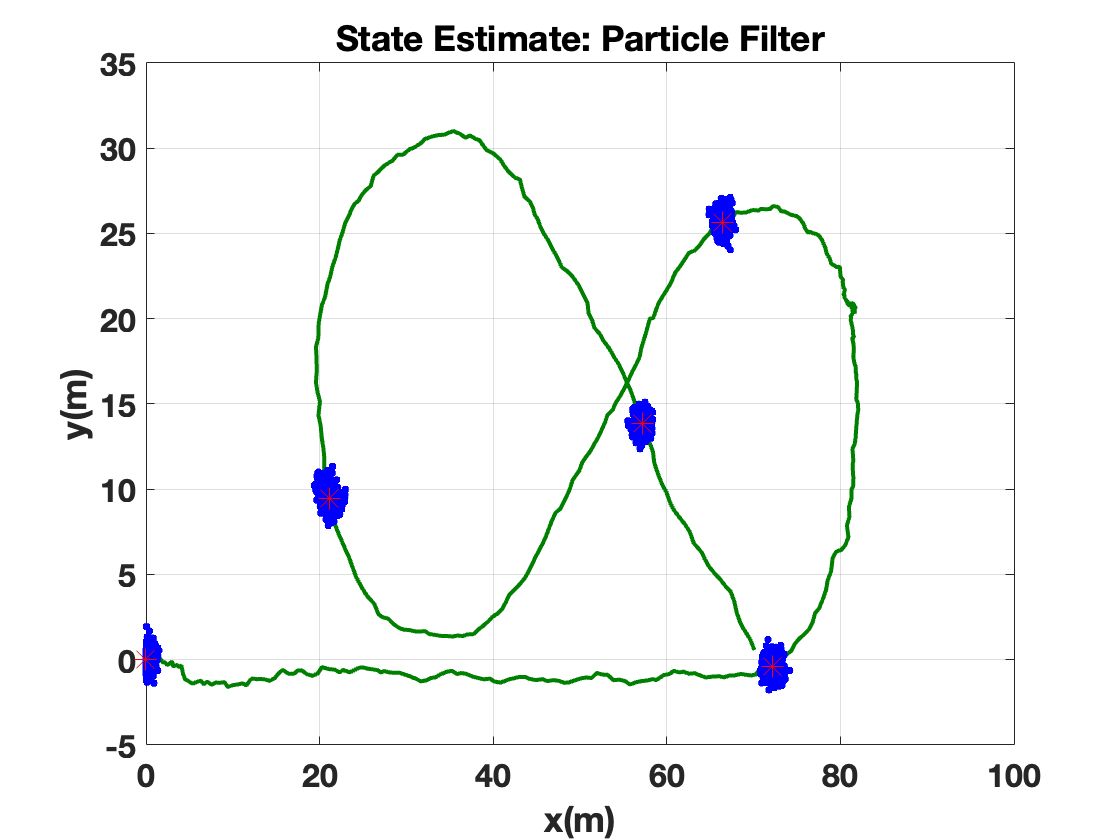

figure(30);
plot_birdseyeview(xEst(:,1:2)',[],[],'State Estimate: Particle Filter');
hold on
hpoint = plot(X(:,1,1),X(:,2,1),'b.','markersize',10);
hEst = plot(xEst(1,1),xEst(1,2),'r*','markersize',10);
plot(X(:,1,150),X(:,2,150),'b.','markersize',10);
plot(xEst(150,1),xEst(150,2),'r*','markersize',10);
plot(X(:,1,300),X(:,2,300),'b.','markersize',10);
plot(xEst(300,1),xEst(300,2),'r*','markersize',10);
plot(X(:,1,400),X(:,2,400),'b.','markersize',10);
plot(xEst(400,1),xEst(400,2),'r*','markersize',10);
plot(X(:,1,500),X(:,2,500),'b.','markersize',10);
plot(xEst(500,1),xEst(500,2),'r*','markersize',10);
xlim([0,100]);
ylim([-5,35]);
hold off

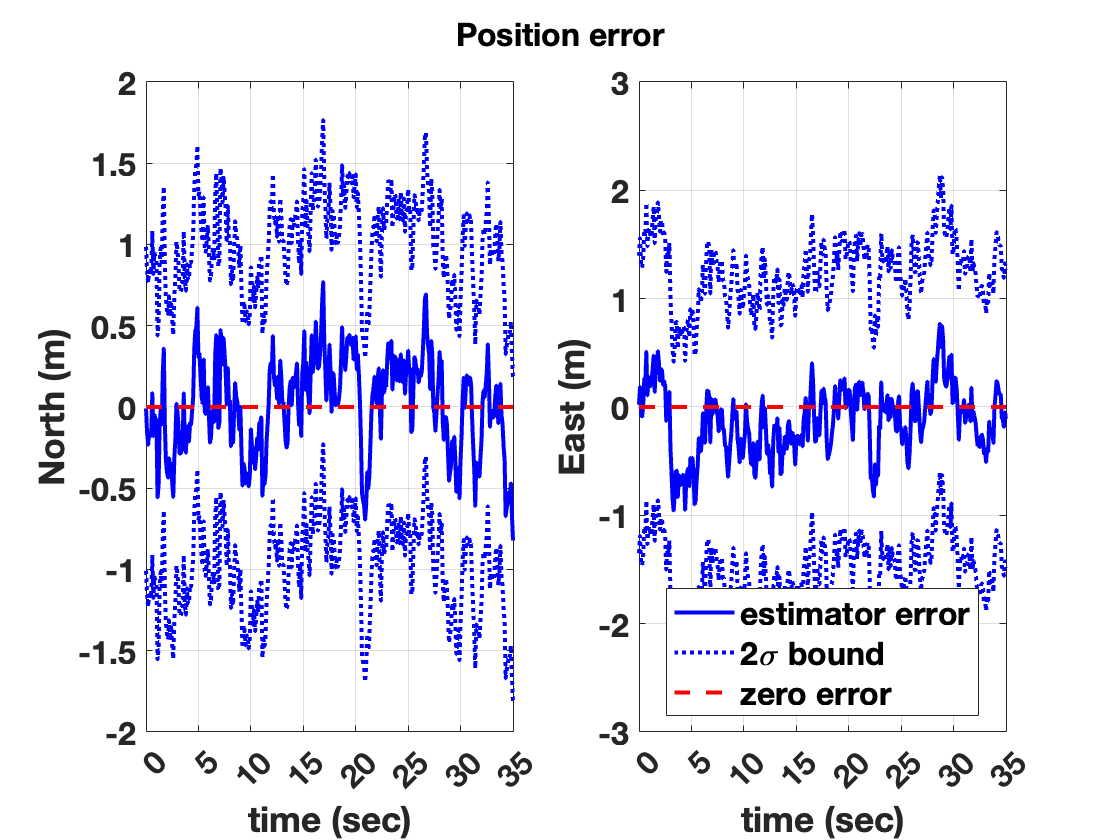

plot_estimator_error(t,Xtrue,xEst',xSig',[1 2],'Position error');

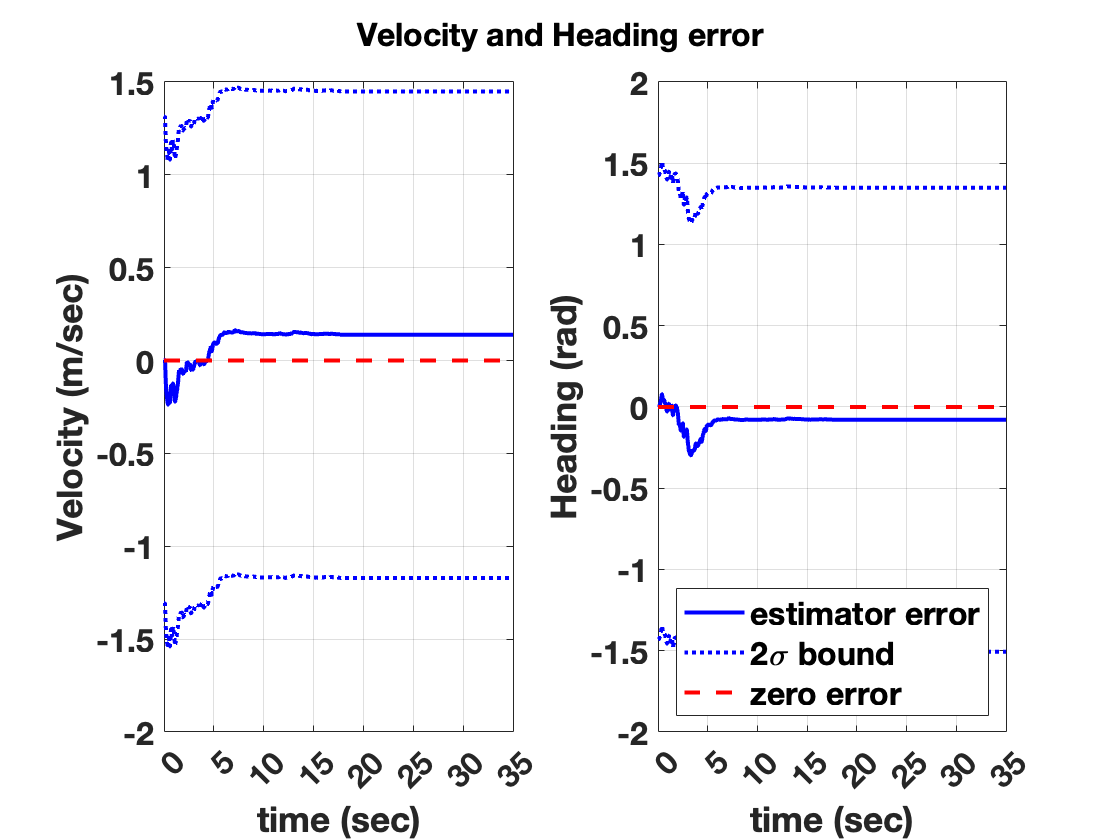

plot_estimator_error(t,Xtrue,xEst',xSig',[3 4],'Velocity and Heading error');


v = VideoWriter('PF','MPEG-4');
v.Quality = 100;
v.FrameRate = 10;
open(v);
for i = 1:nt
    hold on
    figure(2);
%     plot_birdseyeview(xEst(:,1:2)',[],[],'State Estimate: Particle Filter');
    x_particle = X(:,1:2,i);
    set(hpoint,'XData',X(:,1,i));
    set(hpoint,'YData',X(:,2,i));
    set(hEst,'XData',xEst(i,1));
    set(hEst,'YData',xEst(i,2));
    drawnow;
%     pause(0.1);
    frame = getframe(2);
    writeVideo(v,frame);
    hold off
end
close(v);

## Simulation Functions:

function [Uacc,Uomega] = get_controlinputs(scenario_type)

if strcmp(scenario_type,'one')
    Uacc=[ones(1,60) zeros(1,100) -ones(1,60) ones(1,60) zeros(1,50)];
    Uomega=[zeros(1,140) ones(1,40)*pi/2/4 zeros(1,50) ones(1,40)*pi/2/4 zeros(1,60)];
end
if strcmp(scenario_type,'two')
    Uacc=[ones(1,60) zeros(1,100) -ones(1,60) zeros(1,20) ones(1,60) zeros(1,230)];
    Uomega=[zeros(1,140) ones(1,40)*pi/2/4 zeros(1,70) ones(1,60)*pi/2/4 zeros(1,40) -ones(1,60)*pi/8 -ones(1,60)*pi/8 zeros(1, 60)];
end


end

function [Xnonoise]=simulate_2Dbike(Uacc,Uomega,w)
%Simulate state [x,y,V,theta] for bicycle
dt=0.1;
nt=length(Uacc);
t=[0:dt:dt*(nt-1)];
n=4;
Xnonoise=zeros(n,nt);

for i = 1:(nt-1)
    Vk = Xnonoise(3,i);
    Tk = Xnonoise(4,i);
    
    Xnonoise(:,i+1) = Xnonoise(:,i) + dt*[Vk*cos(Tk)+w(1,i);Vk*sin(Tk)+w(2,i);Uacc(i);Uomega(i)];
    
end
end

## SPF Functions:

function [xEst,PxEst,xPred,zPred,innovation]=spf_bike(xEst,PxEst,U,Q,ffun,z,R,hfun,tk,tkp1,nsig)
%-----INITIAL CONSTANTS---------------------------------------------------
nx = length(xEst);  %number of states
nsp=2*nx+1;       %number of sigma points
ensp=ones(1,nsp); %vector of all ones 
%-----GENERATE WEIGHTING MATRICES-----------------------------------------
Wi=0.5/nsig^2;
W0M=(nsig^2-nx)/nsig^2;
W0C=(nsig^2-nx)/nsig^2+3-nsig^2/nx;
%vector form
WM=[W0M;ones(2*nx,1)*Wi];
WC=[W0C;ones(2*nx,1)*Wi];
%--------------------------------------------------
%%-----INITIALIZE-----------------------------------------
Psqrtm = nsig*chol(PxEst)';
xSigmaPts=[zeros(nx,1) -Psqrtm Psqrtm];
xSigmaPts = xSigmaPts + xEst*ensp;
%-----------------------------------------------
%%-----PREDICTION OF SIGMAPOINTS-------------------------------------------
%
%%%%%% Propagate state sigma points through dynamics
xPredSigmaPts = feval(ffun,xSigmaPts,U,zeros([nx,nsp]),tk,tkp1);

%%%%%% Calculate Mean (a priori)
xPred = xPredSigmaPts*WM; 

%%%%% Calculate Covariance (a priori)
exSigmaPts = xPredSigmaPts - xPred*ensp;
PxxPred = exSigmaPts*[diag(WC)]*exSigmaPts' + Q;

%%-----MEASUREMENT UPDATE OF SIGMAPOINTS------------------
%%%% INITIALIZE SIGMA POINTS AGAIN FOR ADDED Q CASE
Psqrtm = nsig*chol(PxxPred)';
exSigmaPts=[zeros(nx,1) -Psqrtm Psqrtm];
xPredSigmaPts = exSigmaPts + xPred*ensp;

%%%% Evaluate predicted state sigma points through output
zPredSigmaPts = feval(hfun,xPredSigmaPts);   

%%%%%% Calculate Measurement Mean
zPred = zPredSigmaPts*WM; 

%%%%%% Calculate Kalman Gain
ezSigmaPts = zPredSigmaPts - zPred*ensp;
PxzPred = exSigmaPts*[diag(WC)]*ezSigmaPts';
Pyy = ezSigmaPts*[diag(WC)]*ezSigmaPts' + R;
K = (PxzPred)*inv(Pyy);

%%%%% Update Covariance 
PxEst = [PxxPred - K*PxzPred'];

%%%%% Calculate Innovation
innovation = z - zPred;
%%%%%% Update mean
xEst = xPred + K*innovation;
end

function Xkp1 = predict_state_bike_euler(Xk,Uk,wk,tk,tkp1)
dt = tkp1 - tk;
[~,nsp]=size(Xk);
Vk = Xk(3,:);
Tk = Xk(4,:);
acc = Uk(1)*ones(1,nsp);
omegadot = Uk(2)*ones(1,nsp);
Xkp1 = Xk + dt*[Vk.*cos(Tk)+wk(1,:);Vk.*sin(Tk)+wk(2,:);acc;omegadot];
end

function Zk = predict_msmt_bike(Xk)
H = [1,0,0,0;
    0,1,0,0;
    0,0,1,0];
Zk = H*Xk;
end

## Plotting Functions

function plot_birdseyeview(x1,x2,P2,title_name)
% x1 is the true value or reference comparison
% x2,P2 is the estimator state and covariance
% 
ii_x1=[];ii_x2=[];ii_P2=[]; %for legend
figure;
if ~isempty(x1)
    plot(x1(1,:),x1(2,:),'color',[0 0.5 0]);ii_x1=1;
end
hold on;
if ~isempty(x2)
    plot(x2(1,:),x2(2,:),'b-');ii_x2=2;
end
if ~isempty(P2)
    iell=[2 10:10:350];
    for i=1:length(iell)
        ii=iell(i);
        [Xe,Ye] = calculateEllipseCov(x2([1 2],ii),P2([1 2],[1 2],ii),3);
        plot(Xe,Ye,'m-');
    end
    ii_P2=3;
end
xlabel('x(m)');ylabel('y(m)');grid;
hold off;
% legend_names={'true trajectory','estimated trajectory','3\sigma bound'};
% legend(legend_names{ii_x1},legend_names{ii_x2},legend_names{ii_P2},'Location','South')
%
title(title_name);
PrepFigPresentation(gcf);
end

function plot_estimator_error(t,x1,x2,P2,ii_plot,title_name)
% x1 is the true value or reference comparison
% x2,P2 is the estimator state and covariance
% ii_plot: 2x1 vector of which states to plot
%
axis_names={'North (m)','East (m)','Velocity (m/sec)','Heading (rad)','Accel Bias (m/sec^2)','RG Bias (rad/sec)'};
figure;subplot(122);
%
for i=1:length(ii_plot)
    ii=ii_plot(i);
    subplot(1,2,i);
    err=x2(ii,:)-x1(ii,:);
    plot(t,err,'b-');
    hold on;
    if ~isempty(P2)
        plot(t,err'-2*sqrt(squeeze(P2(ii,ii,:))),'b:');
        plot(t,zeros(length(t),1),'r--');
        plot(t,err'+2*sqrt(squeeze(P2(ii,ii,:))),'b:');
    end
    hold off
    xlabel('time (sec)');ylabel(axis_names(ii));grid;
    xlim([0 35]);set(gca,'xtick',[0:5:35]);
end
legend('estimator error','2\sigma bound','zero error','Location','South');
%
sgtitle(title_name);
PrepFigPresentation(gcf);
end

function PrepFigPresentation(fignum)
%
% prepares a figure for presentations
%
% Fontsize: 14
% Fontweight: bold
% LineWidth: 2
% 

figure(fignum);
fig_children=get(fignum,'children'); %find all sub-plots

for i=1:length(fig_children)
    
    set(fig_children(i),'FontSize',16);
    set(fig_children(i),'FontWeight','bold');
    
    fig_children_children=get(fig_children(i),'Children');
    set(fig_children_children,'LineWidth',2);
end
end

